# E6 - bis

#### Exercici 1

Calculeu l'histograma dels angles dels gradients d'una imatge (100x100 píxels) generada sintèticament que consisteixi en un degradat de grisos amb origen el centre de la imatge i amb forma de 'flam' gaussià (Two dimensional Gaussian function).

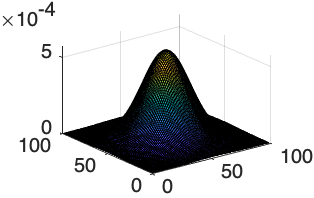

N = 100;
h = fspecial('gaussian',N,N/6);
[X, Y] = meshgrid(1:N,1:N);
surf(X,Y,h);

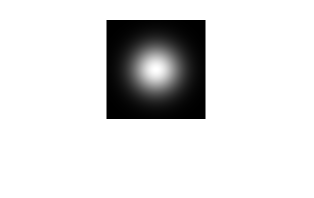

f = h ./ max(h);
I = f .* f'; % Imatge Gaussià
imshow(I);

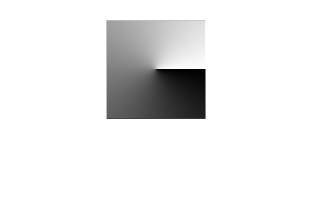


hx = [-1 -2 -1; 0 0 0; 1 2 1];
Gx = imfilter(double(I),hx);
hy = hx';
Gy = imfilter(double(I),hy);
phy = atan2(Gx, Gy) * (180/pi);
imshow(phy, [])

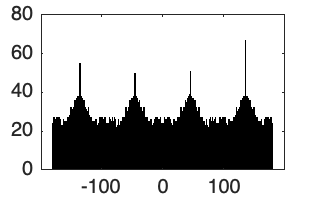


histogram(phy, 360); % Histograma dels angles dels gradients de la imatge

#### Exercici 2

Es vol tenir una útil aplicació de visió per computador que ajudi a trobar a Odlaw, utilitzant el coneixement que la samarreta d’Odlaw està composta de franges negres i grogues. Amb aquest objectiu, caldrà crear una imatge que sigui una mena de mapa tèrmic; que indiqui on les franges negres i grogues (amb prou gruix) es troben. Elimineu les deteccions espúries (petites deteccions) i feu una superposició del mapa tèrmic (en vermell) amb la imatge original (en gris).

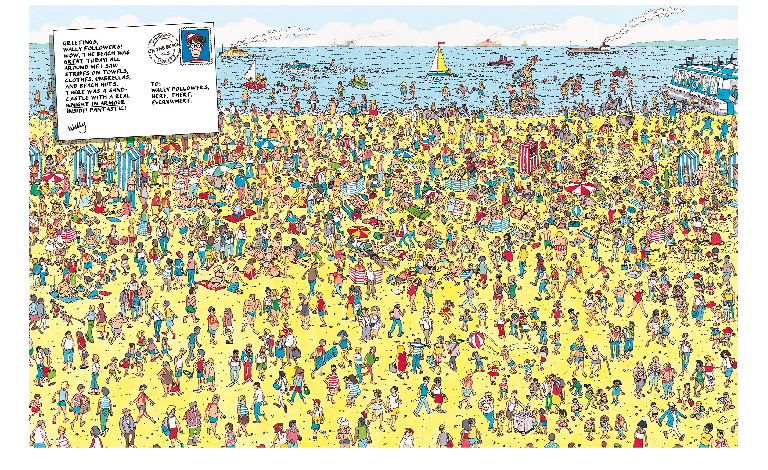

RGB = imread("wally.jpg");
imshow(RGB);

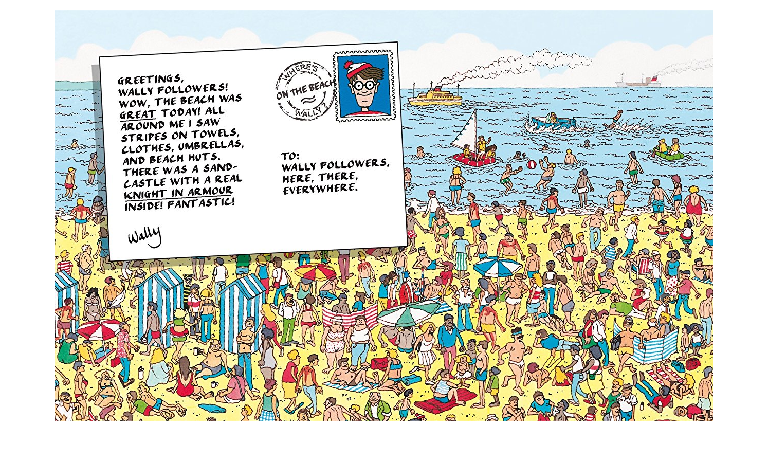

I = rgb2gray(RGB);
[f,c] = size(I);
I = imcrop(RGB,[0 0 c/2 f/2 ]);
imshow(I);

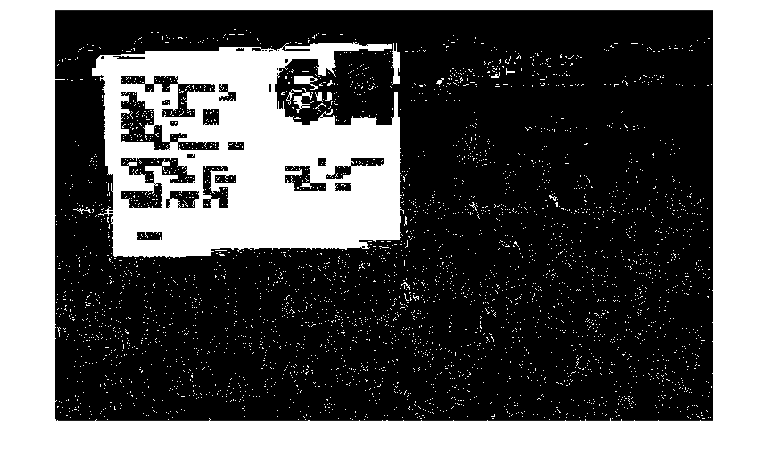


redChannel = I(:,:,1);
greenChannel = I(:,:,2);
blueChannel = I(:,:,3);

I_hsv = rgb2hsv(I);
h = I_hsv(:,:,1); 
s = I_hsv(:,:,2);
v = I_hsv(:,:,3);
yellow = uint8(h < 60/360 & h > 56/360);

black = h < 0.01 & h < 0.01 & h < 0.01;
imshow(black); % detectar el negre 

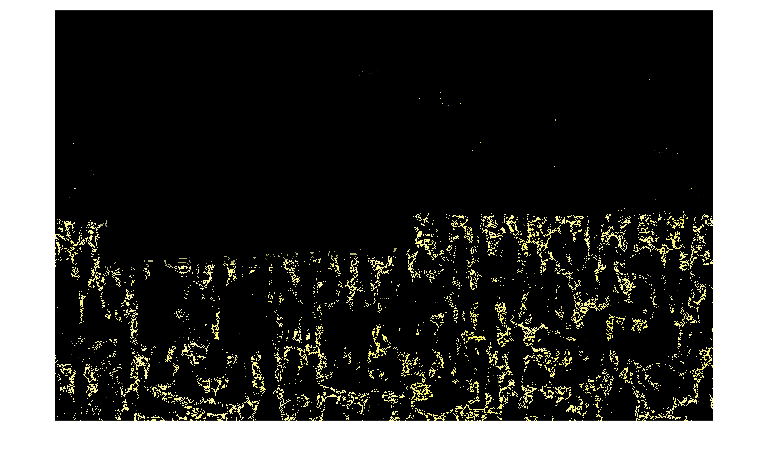

I = I .* yellow; % detectar el groc
imshow(I);